optimParams_v1

Optim Params by using Surrogate optimization for an expensive optimization problems

% Load data
% load pricevolumedata.mat ;
dataInput = load("pricevolumedata.mat")

dataInput = struct with fields:
    closepriceTT: [1212×665 timetable]
     highpriceTT: [1212×665 timetable]
      indexclean: [1212×6 timetable]
      lowpriceTT: [1212×665 timetable]
     openpriceTT: [1212×665 timetable]
        volumeTT: [1212×665 timetable]


% Objective & constraints function
f =  @(x)objconstrFcn(x);
nvars = 11 ;

Define upper, lower bound and constraints

% Define upper, lower and bound 
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
lb              = [60   50  2   50  2   0   60  5   3   1   0] ;
ub              = [250  100 60  100 10  15  250 30  5   5   8] ;

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 


% Integer constraints
intcon = 1:nvars ;

% Set options
opts = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot","ConstraintTolerance",1e-2, "UseParallel", true);


Call `surrogateopt` to solve the problem

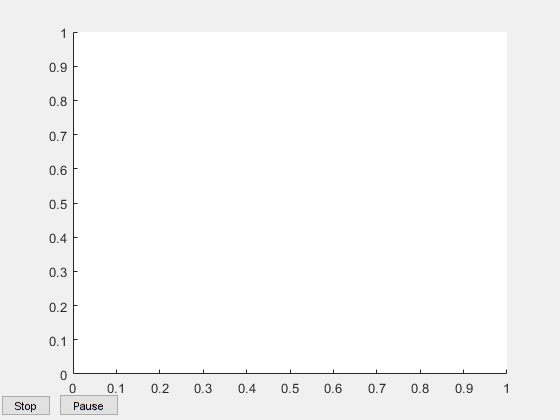

Error using parallel.FevalFuture/fetchNext
The function evaluation completed with an error.

Error in globaloptim.bmo.ModelManager/getNext (line 155)
                    [~, self.pendingTrials(fetchID).output] = fetchNext(self.pendingTrials(fetchID).task);

Error in 

% Call surrogateopt to solve the problem
rng default % For reproducibility
[sol,fval,eflag,outpt] = surrogateopt(f,lb,ub,intcon,opts)